n=0:1:9;x=cos(0.48 *pi*n)+cos(0.52 *pi*n);
w=(0:1:5001)*2*pi/500;
X=x*exp(-1i*n'*w) ;
magx = abs(X);
x1 = fft(x); magx1 = abs(x1(1: 1:10))

magx1 =     1.8460    2.2867    6.2141    6.2141    2.2867    1.8460    2.2867    6.2141    6.2141    2.2867


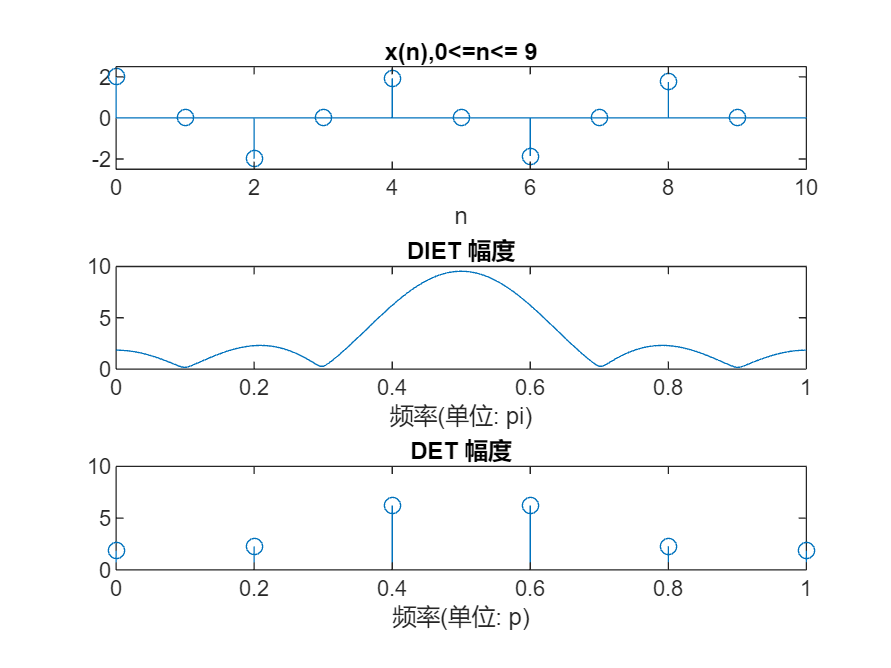

k1=0:1:9;w1=2*pi/10*k1;
subplot(3,1,1);stem(n,x); title('x(n),0<=n<= 9');
xlabel('n');
axis([0,10,-2.5,2.5]);line([0,10],[0,0]);
subplot(3,1,2);plot(w/pi,magx); title('DIET 幅度');
xlabel('频率(单位: pi)');
axis([0,1,0,10]);
subplot(3,1,3);stem(w1/pi,magx1);title('DET 幅度');
xlabel('频率(单位: p)');axis([0,1,0,10])

n=0:1:9;y=cos(0.48*pi*n)+cos(0.52*pi*n);
n1=0:1:99;x=[y(1:1:10) zeros(1,90)];
w=(0:1:500)*2*pi/500;
X=x*exp(-1i*n1'*w);magx=abs(X);
x1=fft(x);magx1=abs(x1(1:1:50));
k1=0:1:49;w1=2*pi/100*k1;


%plot statements
